# Eksamensæt E20

**M3NUM1 Anvendte Numeriske Metoder -- 16-01-2023**

**Mathias Bruun Houmøller -- 202006837 -- Au666097**

## Opgave 1

clear
format short %formater resultater til 4 decimaler
u = symunit; %Laver symbolske si enheder
% separateUnits(x)
% unitConvert(expr,units)

Figur 1 viser et virkningsgradsdiagram for en mindre dieselmotor, dvs. virkningsgraden (i %) som funktion af motorakslens omdrejningstal (i antal 1000 omdrejninger/minut = kRPM) og mo-mentbelastning (i kNm). Funktionssammenhæn-gen er kun gældende inden for et afgrænset om-råde, hvilket også fremgår af diagrammet.

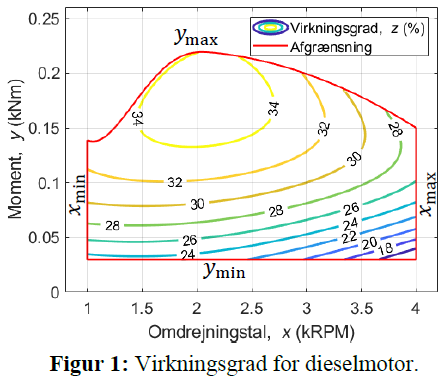

### (1a)

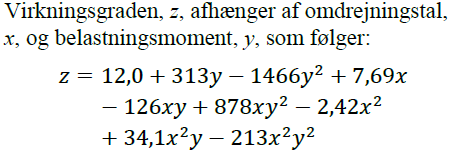

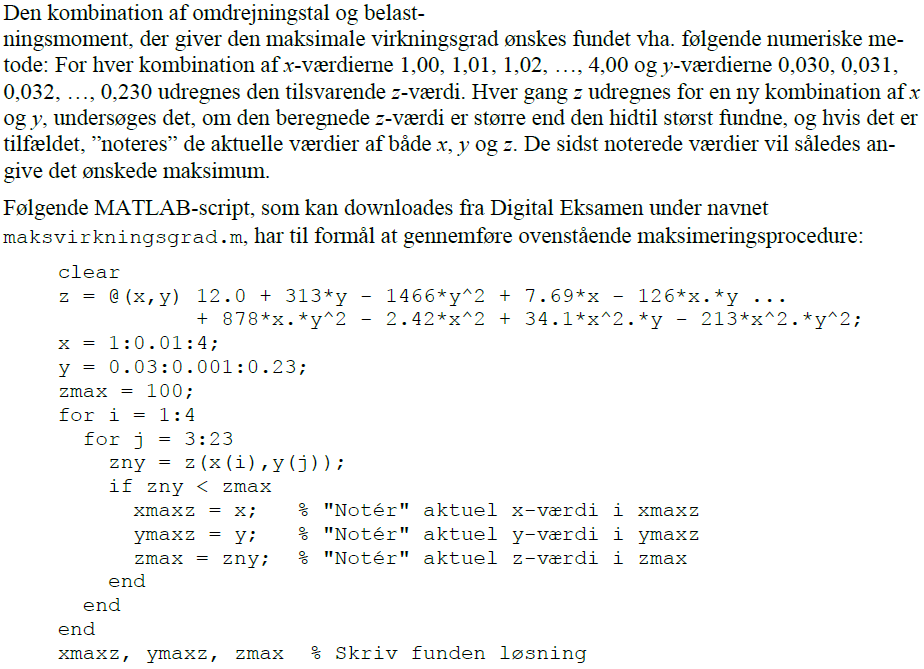

clear
z = @(x,y) 12.0 + 313*y - 1466*y^2 + 7.69*x - 126*x.*y ...
    + 878*x.*y^2 - 2.42*x^2 + 34.1*x^2.*y - 213*x^2.*y^2;
x = 1:0.01:4;
y = 0.03:0.001:0.23;
zmax = 0; % start med 0 da vi skal finde den største z-værdi
for i = 1:length(x) %der gennemgåes alle x værdier
    for j = 1:length(y) % der gennemgåes alle y værdier for hver x-værdi
        zny = z(x(i),y(j));
        if zny > zmax %Z-værdien skal være størrer end zmax for at blive noterede
            xmaxz = x(i); % "Notér" aktuel x-værdi i xmaxz
            ymaxz = y(j); % "Notér" aktuel y-værdi i ymaxz
            zmax = zny; % "Notér" aktuel z-værdi i zmax
        end
    end
end
xmaxz, ymaxz, zmax % Skriv funden løsning

xmaxz = 2.1100

ymaxz = 0.1770

zmax = 35.0691

Således den største virkningsgrad der kan opnåes er $z = 35,07$%.

### (1b)

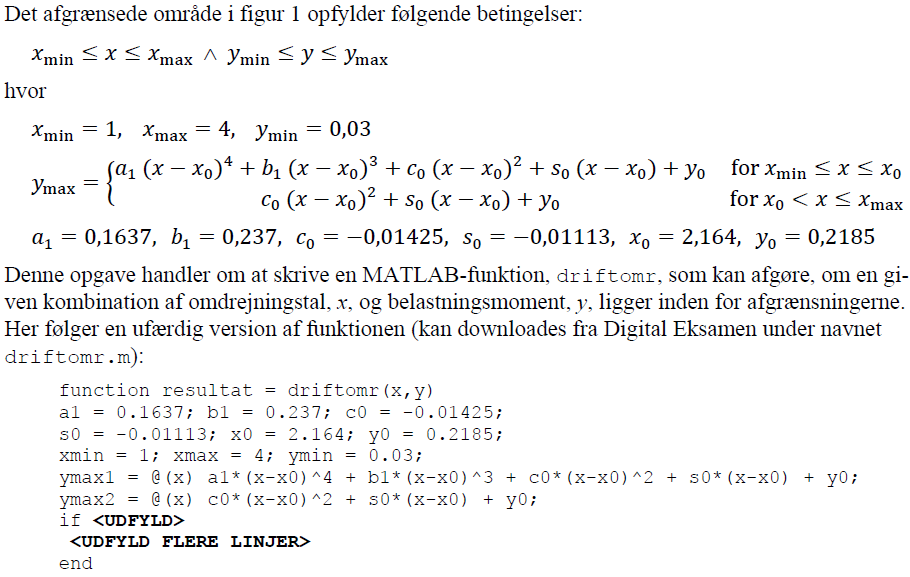

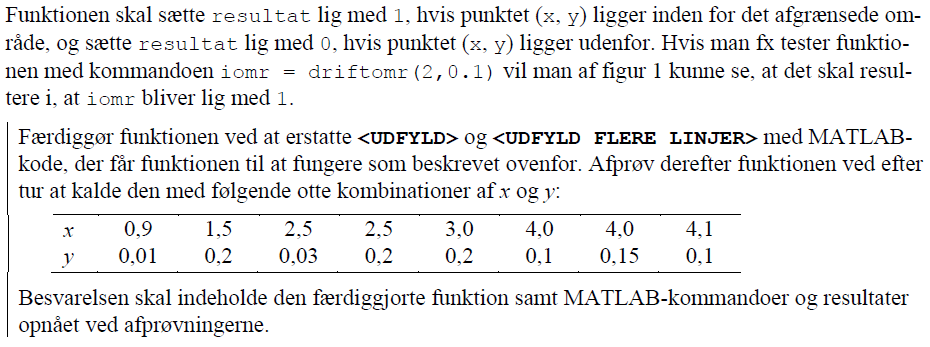

x = [0.9 1.5 2.5 2.5 3.0 4.0 4.0 4.1];
y = [0.01 0.2 0.03 0.2 0.2 0.1 0.15 0.1];
iomr = driftomr(2,0.1) %test

iomr = 1

n = length(x);
iomrs = zeros(n,1); %laver en vector med presat størrelse for at spare hukkomelse.
for i = 1:length(x)
    iomrs(i) = driftomr(x(i),y(i));
end
disp(table(x',y', iomrs,'VariableNames',{'x','y', 'i området 1=ja'}))

     x      y      i området 1=ja
    ___    ____    ______________

    0.9    0.01          0       
    1.5     0.2          0       
    2.5    0.03          1       
    2.5     0.2          1       
      3     0.2          0       
      4     0.1          1       
      4    0.15          1       
    4.1     0.1          0       



## Opgave 2

clear

Betragt igen som i opgave 1 virkningsgrad, z (%), som funktion af omdrejningstal, x (kRPM), og belastningsmoment, y (kNm) for en mindre dieselmotor:

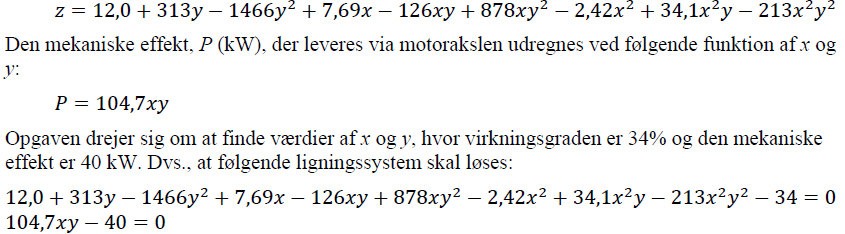

### (2a)

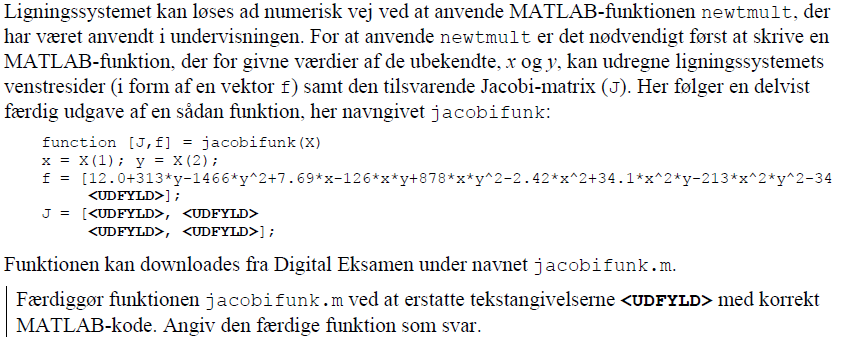

Vi finder først de partielt afledte af x og y som

syms x y

f = [12.0+313*y-1466*y^2+7.69*x-126*x*y+878*x*y^2-2.42*x^2+34.1*x^2*y-213*x^2*y^2-34
     104.7*x*y - 40];

for i = 1:length(f)
    fprintf(" Ligning %d patielt differentiert for alle varable", i)
    disp('for x')
    vpa(diff(f(i), x))
    disp('for y')
    vpa(diff(f(i), y))
    disp('')
end

 Ligning 1 patielt differentiert for alle varable

for x


$$ans = 68.2\,x\,y-126.0\,y-4.84\,x-426.0\,x\,y^{2}+878.0\,y^{2}+7.69$$

for y


$$ans = 1756.0\,x\,y-2932.0\,y-126.0\,x-426.0\,x^{2}\,y+34.1\,x^{2}+313.0$$

 Ligning 2 patielt differentiert for alle varable

for x


$$ans = 104.7\,y$$

for y


$$ans = 104.7\,x$$

Vi bruger det afledte ligninger til at indsætte i jacobi matrixen. vi har nu funktionen

### (2b)

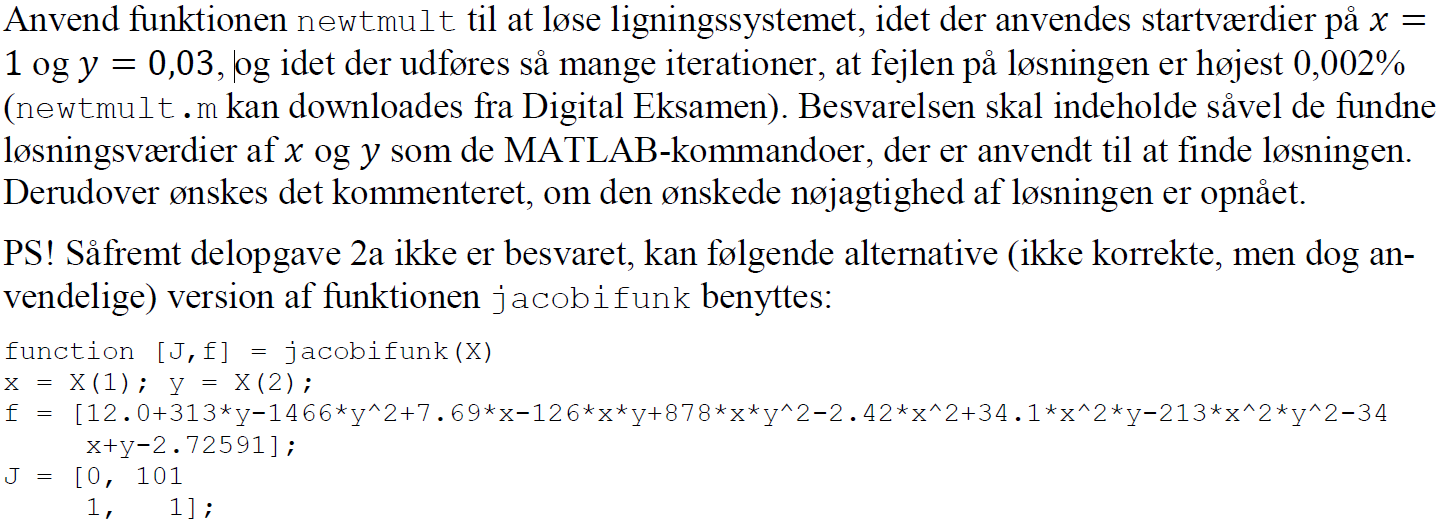

x_s = 1;
y = 0.03;
x0 = [x_s; y];
es = 0.002;
% maxit = 100;
func = @jacobifunk;

[x,f,ea,iter] = newtmult(func,x0,es)

x =    2.577703961909160
   0.148210943032072


f = 1.0e-04 *

  -0.115701017904257
  -0.193169517430647


ea =      1.373382401026748e-04


iter =     10


Vi får nu $x=2,578$kRPM og $y=0,148$kNm med en usikkerhed på 0,000137%  og vi har dermed opnået den ønskede nøjagtighed som var 0,002%.

### (2c)

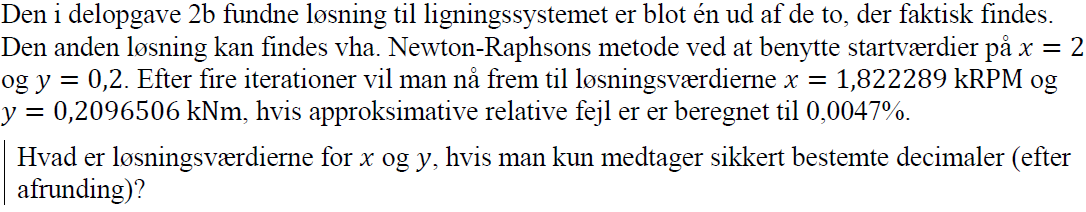

format long
x = 1.822289;
y = 0.2096506;
err = 0.0047 / 100;

x_err = x * err;
y_err = y * err;

x_with_err = [x - x_err, x + x_err]

x_with_err =    1.822203352417000   1.822374647583000


y_with_err = [y - y_err, y + y_err]

y_with_err =    0.209640746421800   0.209660453578200


For x skal man afrunde til tre decimaler, for at intervalendepunkterne bliver ens, nemlig så man får resultatet 1,822. For y skal man ligeledes afrunde til tre decimaler, for at intervalendepunkterne bli-ver ens, nemlig så man får resultatet 0,210. Løsningen med sikre afrundede decimaler er derfor:

𝑥=1,822 kRPM;𝑦=0,210 kNm.

## Opgave 3

clear

### (3a)

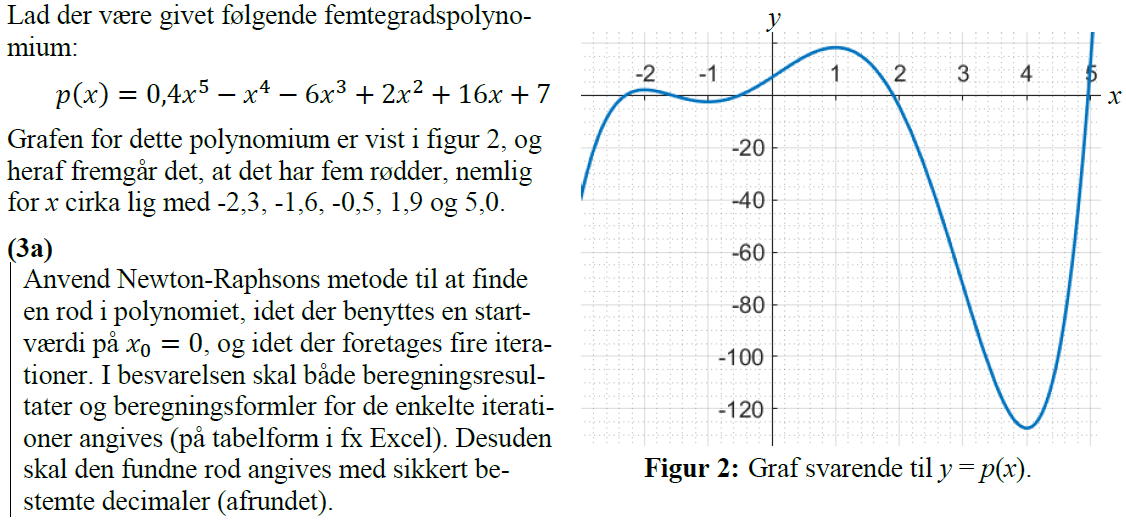

Ligningen differentiers

syms x
p = 0.4*x^5 - x^4 - 6*x^3 + 2*x^2 + 16*x + 7;
p_1 = diff(p, x)

$$p\_1 = 2\,x^{4}-4\,x^{3}-18\,x^{2}+4\,x+16$$

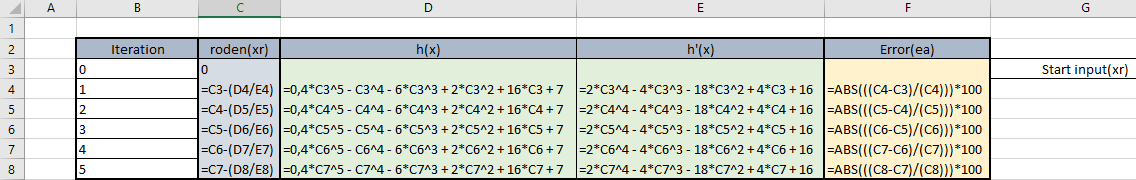

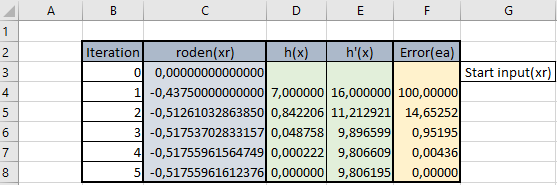

Vi får således roden $-0,51755962$

### (3b)

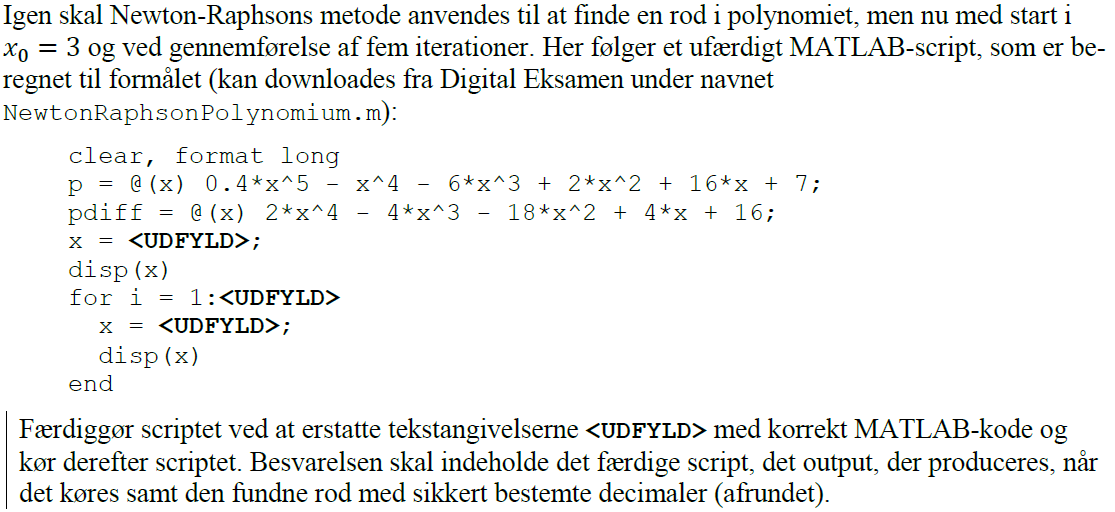

clear, format long
p = @(x) 0.4*x^5 - x^4 - 6*x^3 + 2*x^2 + 16*x + 7;
pdiff = @(x) 2*x^4 - 4*x^3 - 18*x^2 + 4*x + 16;
x = 3;
disp(x)

     3



for i = 1:5
  x = x - p(x)/pdiff(x);
  disp(x)
end

   2.090000000000000

   1.924121538104697

   1.908032816033752

   1.907874720973848

   1.907874705686683



**Således for vi roden 1,9078747 da iteration 4 og 5 er ens ned til 7 decimaler.**

### (3c)

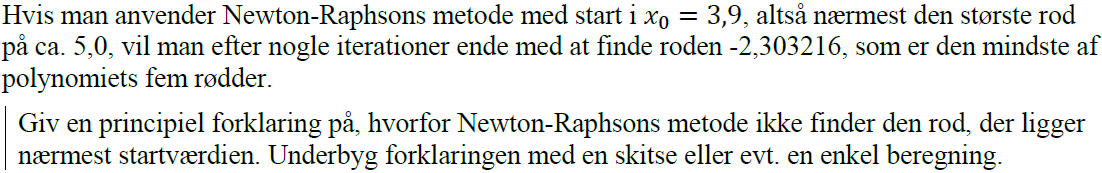

Dette sker fordi vi vi har en positiv x værdi 3,9 hvor der trækkes en negativ y værdie dividere med en negativ hældningskoeficient dydx. hvis vi følger hældningen op til x-linjen finder vi nu vores nye x-værdi som giver anledning til en positiv y-værdie og positiv hældning tæt på roden som -2,303216 som der nu søges hen imod.'

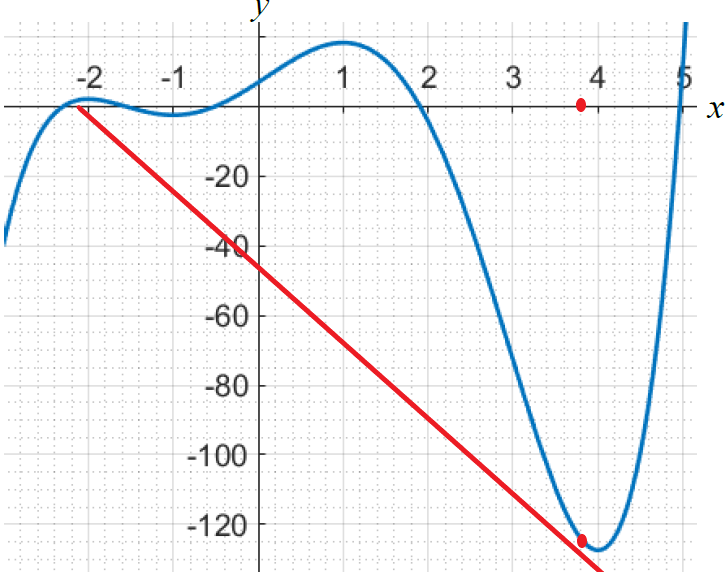

Fra løsningsforslaget

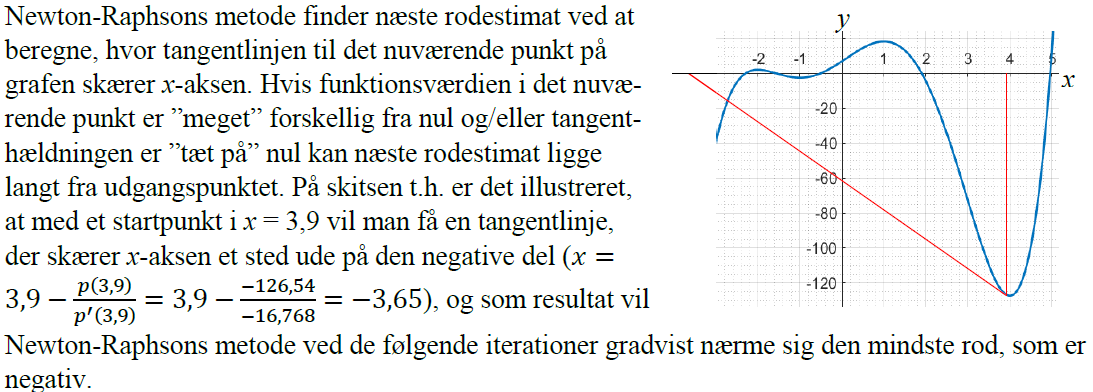

### (3d)

Hvis man anvender Newton-Raphsons metode med start i 𝑥0=−1, kan man ikke iterere sig frem til en rod. Forklar hvorfor? Underbyg forklaringen med en relevant beregning.

p(-1)

ans =   -2.400000000000000


pdiff(-1)

ans =      0


Det ses at hældningen bliver 0 og da vi ikke kan dividere med 0 i formlen $x = -1 - \frac{-2,4}{0}$  kan der ikke findes en ny x-værdi.

### (3e)

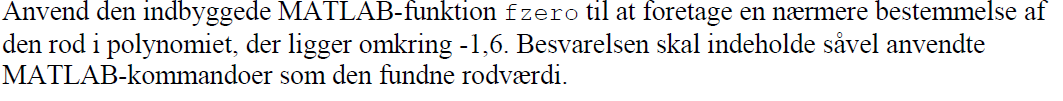

fzero(p,-1.6)

ans =   -1.550342596600663


**Således bliver roden -1,5503.**

### (3f)

Benyt den indbyggede MATLAB-funktion *roots* til at bestemme samtlige rødder i polynomiet. Besvarelsen skal indeholde såvel anvendte MATLAB-kommandoer som fundne rodværdier.

C = [0.4 -1 -6 2 16 7]; % vi tager coeficienterne fra femtegrads polynomiet.

C =    0.400000000000000  -1.000000000000000  -6.000000000000000   2.000000000000000  16.000000000000000   7.000000000000000


rodder = roots(C)

rodder =    4.963243089469575
   1.907874705686681
  -2.303215582431840
  -1.550342596600662
  -0.517559616123756


**De fem rødder er således, 4,9632, 1,9079, -2,3032, -1,5503 og -0,5176.**

## Opgave 4

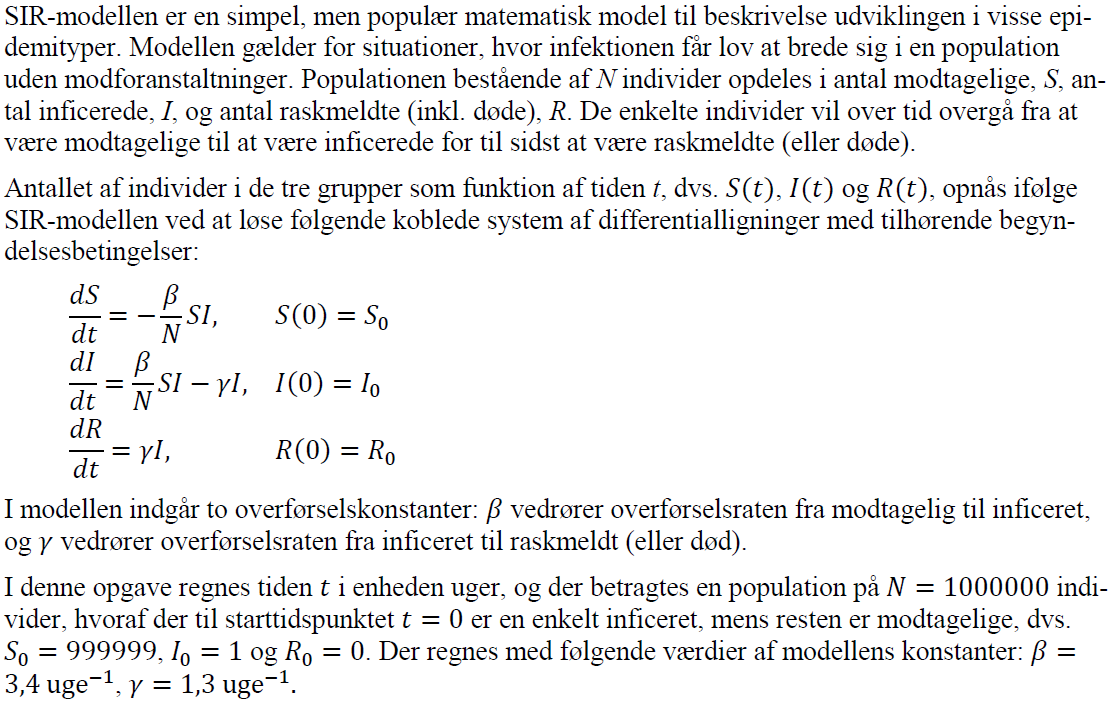

### (4a)

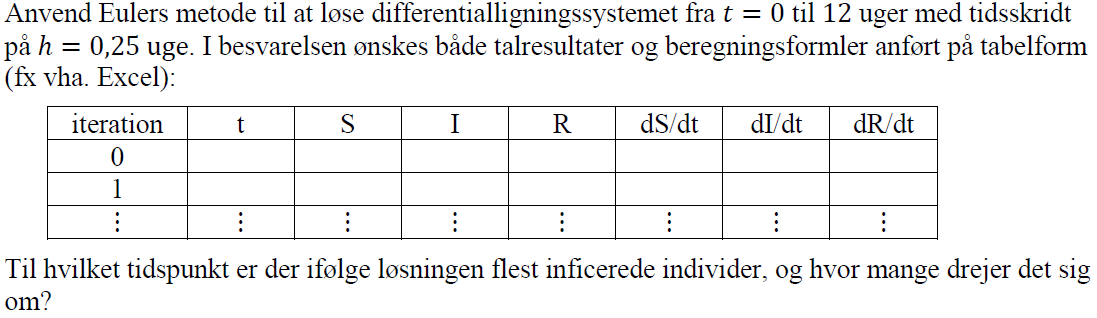

clear
format long
S0 = 999999;
I0 = 1;
R0 = 0;
beta = 3.4; %uger^-1
gamma = 1.3; %uger^-1
N = 1000000;

t_start = 0;
t_slut = 12;

% dSdt = - beta / N * SY(1) * IY(2);
% dIdt = beta/N * SY(1) * I - gamma * IY(2);
% dRdt = gamma * IY(2);

% S = Y(1)
% I = Y(2)
% R = Y(3)

dYdt = @(t,Y) [- beta / N * Y(1) * Y(2), beta/N * Y(1) * Y(2) - gamma * Y(2), gamma * Y(2)]; 
Y0 = [S0 I0 R0]; 
tidsinterval = [t_start t_slut]; 
h = 0.25; %uger
[t,Y] = eulsys(dYdt,tidsinterval,Y0,h); 
S = Y(:,1); 
I = Y(:,2); 
R = Y(:,3); 

disp(table(t,S,I,R,'VariableNames',{'t, uger','S, antal modtagelige','I, antal syge','R, raske/døde'}))

    t, uger    S, antal modtagelige     I, antal syge       R, raske/døde  
    _______    ____________________    ________________    ________________

         0                 999999                     1                   0
      0.25        999998.15000085            1.52499915               0.325
       0.5       999996.853753971      2.32562130568994       0.82062472375
      0.75        999994.87698208      3.54656627174688    1.57645164809923
         1       999991.862416193      5.40849812065981    2.72908568641696
      1.25       999987.265230201      8.24792222371549     4.4868475756314
       1.5       999980.254585591      12.5779921110839    7.16742229833894
      1.75         999969.5635034      19.1812268653863    11.2552697344412
         2       999953.259956803      29.2508747317698    17.4891684656917
      2.25        999928.39

I_max = max(I)

I_max =      2.797560714364119e+05


result = find(I==max(I))

result =     34


t(34)

ans =    8.250000000000000


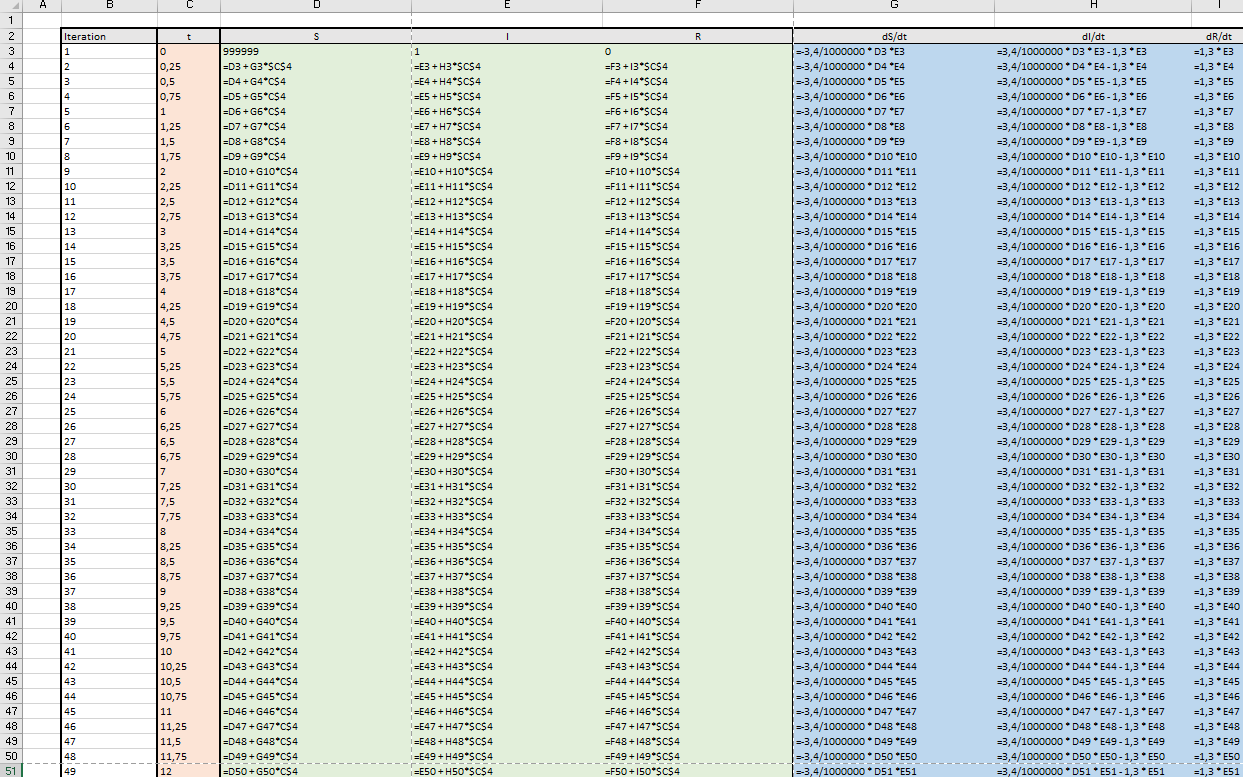

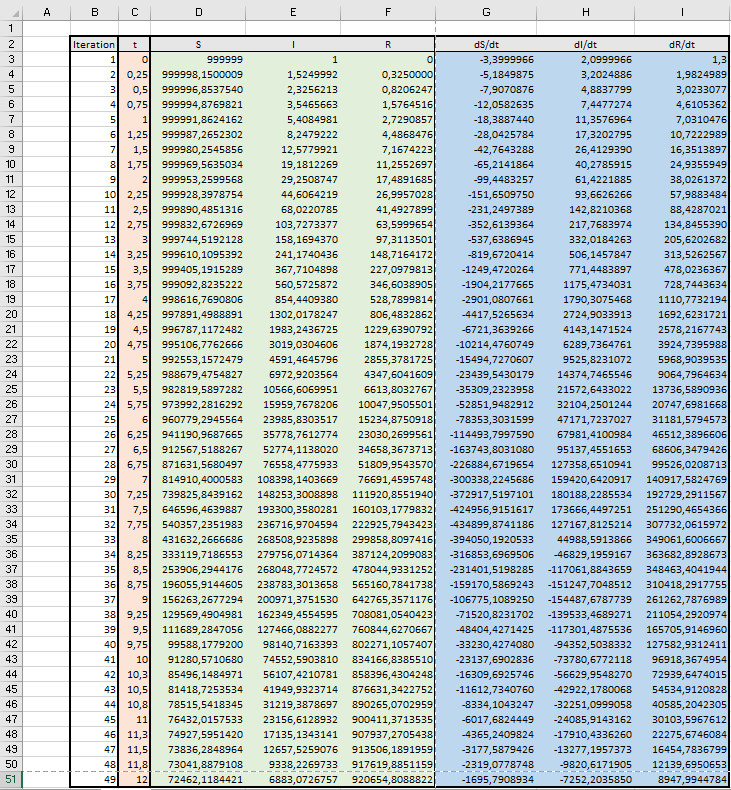

**Det maximale antal inficerede I er 279.756 personer efter 8,25 uger.**

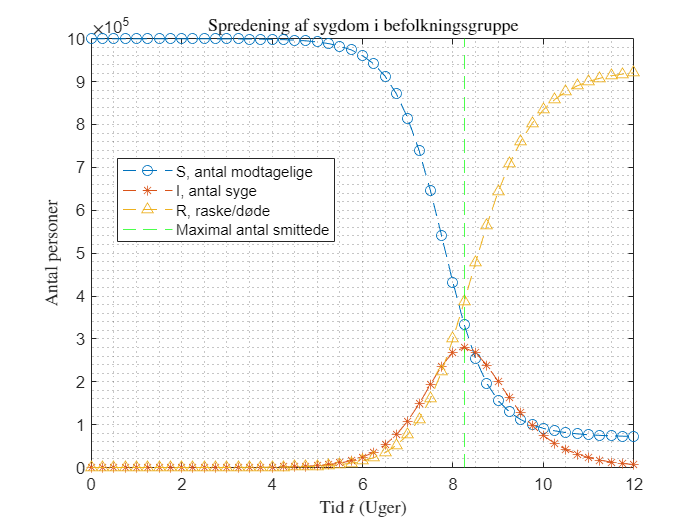

% der plottes
plot(t,S,'--o', 'DisplayName', 'S, antal modtagelige') %data plottes'','',''
hold on
plot(t,I,'--*', 'DisplayName', 'I, antal syge') 
plot(t,R,'--^', 'DisplayName', 'R, raske/døde') 
xline(8.25, 'g--', 'DisplayName', 'Maximal antal smittede')

% formalier
legend('location', 'best')
title('Spredening af sygdom i befolkningsgruppe', 'interpreter', 'latex')
xlabel('Tid $t$ (Uger)', 'interpreter', 'latex')
ylabel('Antal personer', 'interpreter', 'latex')
grid('minor')
hold off

### (4b)

For at opnå en mere nøjagtig numerisk løsning af differentialligningssystemet kan en fjerdeordens Runge-Kutta-metode anvendes. Metoden kan gennemføres vha. MATLAB-funktionen

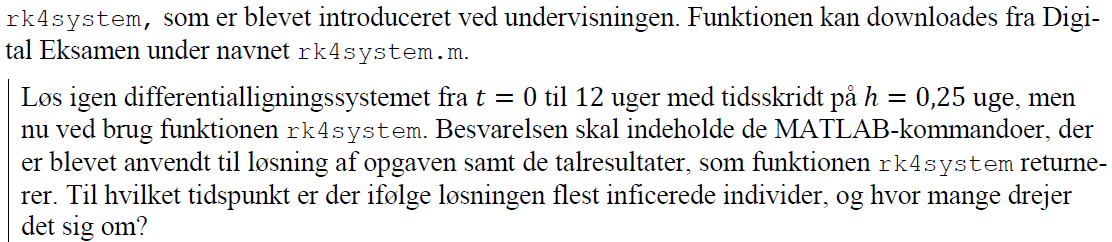

[t,Y] = rk4system(dYdt,tidsinterval,Y0,h);
S = Y(:,1); 
I = Y(:,2); 
R = Y(:,3); 

disp(table(t,S,I,R,'VariableNames',{'t, uger','S, antal modtagelige','I, antal syge','R, raske/døde'}))

    t, uger    S, antal modtagelige     I, antal syge        R, raske/døde  
    _______    ____________________    ________________    _________________

         0                 999999                     1                    0
      0.25       999997.882705647      1.69009290413496    0.427201448917674
       0.5       999995.994378393      2.85641046515213     1.14921114154479
      0.75       999992.802945316      4.82758287543495     2.36947180856982
         1        999987.40917767      8.15900716980304     4.43181516039674
      1.25       999978.293365569      13.7893018630981     7.91733256791681
       1.5       999962.887261931      23.3046630256508     13.8080750433065
      1.75       999936.850878109      39.3854592833175     23.7636626082306
         2       999892.850917152      66.5604715560072     40.5886112923719
      2.25      

I_max = max(I)

I_max =      2.493341874491070e+05


result = find(I==max(I))

result =     28


t(28)

ans =    6.750000000000000


**Der er nu maximalt antal smittede efter 6,75 uger med 249334 personer.**

### (4c)

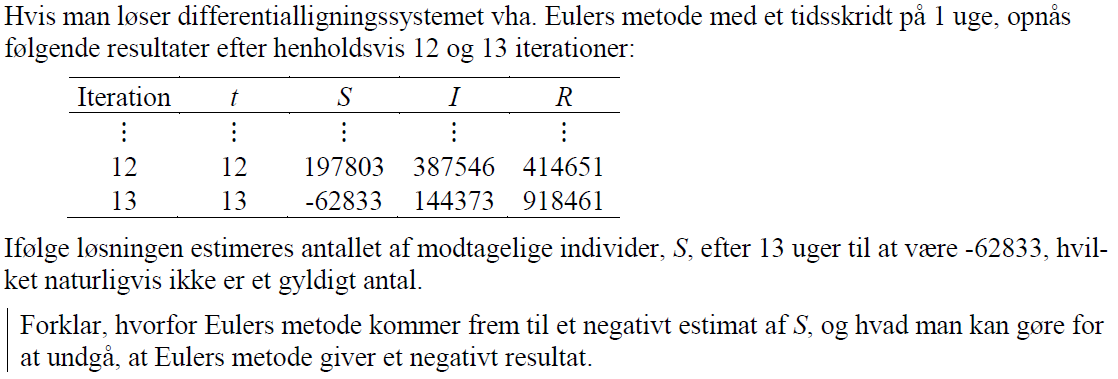

Vi plotter den nye situation for at få et overblik

t_start = 0;
t_slut = 14;

dYdt = @(t,Y) [- beta / N * Y(1) * Y(2), beta/N * Y(1) * Y(2) - gamma * Y(2), gamma * Y(2)]; 
Y0 = [S0 I0 R0]; 
tidsinterval = [t_start t_slut]; 
h = 1; %uger
[t,Y] = eulsys(dYdt,tidsinterval,Y0,h); 
S = Y(:,1); 
I = Y(:,2); 
R = Y(:,3); 

disp(table(t,S,I,R,'VariableNames',{'t, uger','S, antal modtagelige','I, antal syge','R, raske/døde'}))

    t, uger    S, antal modtagelige      I, antal syge       R, raske/døde  
    _______    ____________________    _________________    ________________

       0                   999999                      1                   0
       1           999995.6000034              3.0999966                 1.3
       2         999985.060061336        9.6099430840867          5.32999558
       3         999952.386742995       29.7903354160039    17.8229215893127
       4         999851.104425191       92.3452171789643    56.5503576301178
       5         999537.177436083       286.223423954534    176.599139962771
       6         998564.468194878       886.842214018701    548.689591103666
       7         995553.533173909       2744.88235676319    1701.58446932798
       8         986262.430257273       8467.63820960692    5269.93153312012
       9        

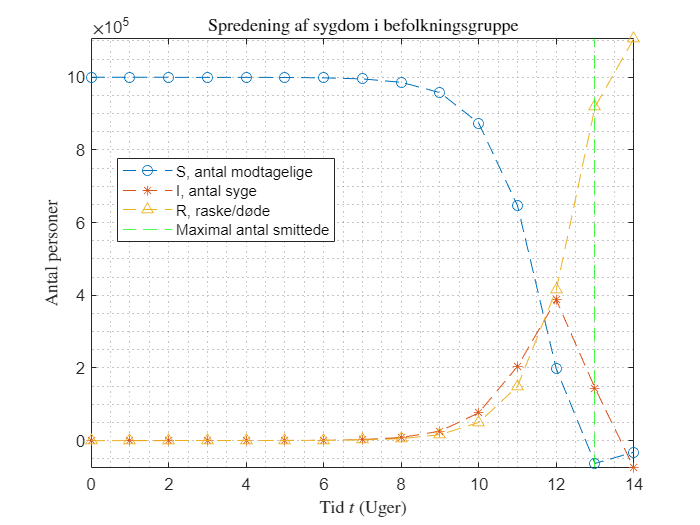

% der plottes
plot(t,S,'--o', 'DisplayName', 'S, antal modtagelige') %data plottes'','',''
hold on
plot(t,I,'--*', 'DisplayName', 'I, antal syge') 
plot(t,R,'--^', 'DisplayName', 'R, raske/døde') 
xline(13, 'g--', 'DisplayName', 'Maximal antal smittede')

% formalier
legend('location', 'best')
title('Spredening af sygdom i befolkningsgruppe', 'interpreter', 'latex')
xlabel('Tid $t$ (Uger)', 'interpreter', 'latex')
ylabel('Antal personer', 'interpreter', 'latex')
grid('minor')
hold off

**Vi ser at skridtene der tages er så store at kurven når at komme under 0 imellem skridt 12 og 13, da der bruges en lineær fremskrivning. For at få et mere præcist resultat skal der tages den del mindre skridt.**

**Fra løsnings forslag**